Fs = 10E6           % Sample rate: 10 MHz

Fs = 10000000

C1 = 38.72E-12      % Load cap: 38.72 pF

C1 = 3.8720e-11

N_sample = 1024     % Sampled point: 1024

N_sample = 1024

V0 = 0.895;         % Input range: 0.895*2 V
VDD = 1.8;          % Supply: 1.8 V
VCM = 0.9;          % Common mode: 0.9 V
Ron0 = 210*3;       % On-state ron


## Fixed Fin and Cboot

Cb = 1E-12;                     % unit: F
Fin = 499/N_sample*Fs;          % Input frequency: 5 MHz
win = 2*pi*Fin                  % Input frequency: 10Mpi rad/s

win = 3.0618e+07

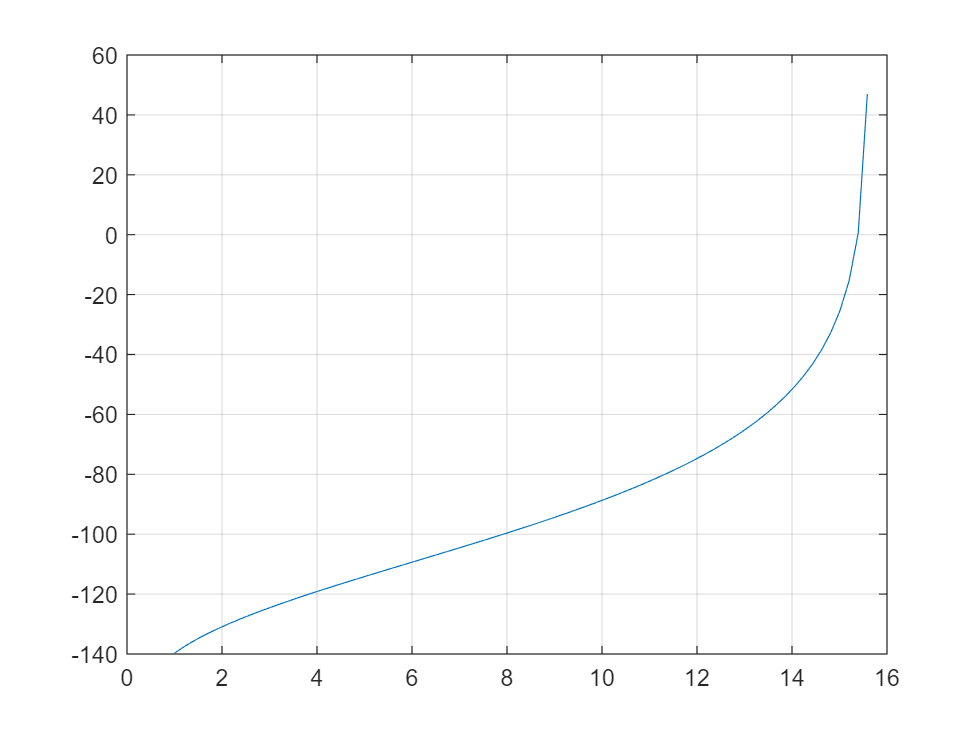

w = 32.*linspace(1,20,100);     % unit: um
cp2 = 2.*w.*(1E-15);            % unit: F
cp3 = cp2;
c_tot = Cb + cp2 + cp3;         

vgs_dc = (Cb*VDD - (cp2+cp3).*VCM)./c_tot;
k1 = cp2 + cp3.*cos(win/Fs);
k2 = -cp3*sin(win/Fs);
k = sqrt(k1.^2 + k2.^2)./c_tot;
vgs_delta = V0.*k;

ron = (Ron0*VDD) ./w ./vgs_dc;
HD3 = (0.5*C1*win) .* ron .* (vgs_delta./vgs_dc).^2;
HD3_db = mag2db(HD3);

figure
hold on
grid on; box on;
plot(w./32, HD3_db)

% 考虑ADC输入电阻的问题
% 仿真结果也证明这一点，导通电阻越大，对于HD3来说表现越佳；

% 
% figure
% plot(w./32, HD3_db, w./32, HD3_db_5p);
% grid on; hold on;
% xlabel("W [um] (m=32,L=200n)");
% ylabel("HD3 [dB]");
% xlim([1,10]);
% legend(["Cboot = 1 pF"; "Cboot = 0.5 pF"], "Location","northwest")